clear
skidpad_data = readtable('skidpad2_50hz.csv');

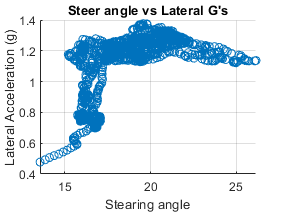


start_t = 250;
end_t = 1350;
m_k = 40;

accelY = movmean(skidpad_data.AccelY,m_k) ;
accelY = accelY(start_t:end_t);

str_a = movmean(skidpad_data.SteeredAngle, m_k);
str_a = str_a(start_t:end_t);

t = skidpad_data.Time;
t = t(start_t:end_t);

wheelspeed_avg = movmean(mean([skidpad_data.WheelSpdRL,skidpad_data.WheelSpdRR,...
    skidpad_data.WheelSpdFL,skidpad_data.WheelSpdFR]'),m_k);
wheelspeed_avg = wheelspeed_avg(start_t:end_t);

roll = movmean(skidpad_data.Roll(start_t:end_t),m_k);




% speed = medfilt1(1/2.*t.^2.*skidpad_data.AccelX(250:1300),10);
figure(1)
scatter(str_a, accelY), title("Steer angle vs Lateral G's"),...
    xlabel('Stearing angle'),ylabel('Lateral Acceleration (g)'),grid

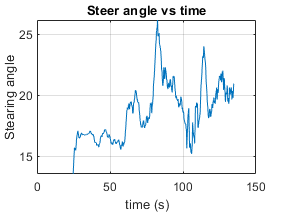

figure(2)
plot(t, str_a), title('Steer angle vs time'),...
    xlabel('time (s)'),ylabel('Stearing angle'),grid

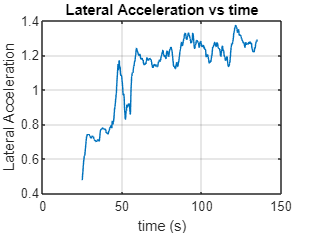

figure(3)
plot(t,accelY), title('Lateral Acceleration vs time'),...
    xlabel('time (s)'),ylabel('Lateral Acceleration'),grid

figure(4)
plot(t,wheelspeed_avg), title('Wheel speed (4 wheel avg) vs time'),...
    xlabel('time (s)'),ylabel('Wheel speed'),grid

wheelspeed_avg = wheelspeed_avg';
f = fit(wheelspeed_avg,str_a,'poly1')

f =      Linear model Poly1:
     f(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.4395  (0.4026, 0.4765)
       p2 =       6.864  (5.864, 7.864)

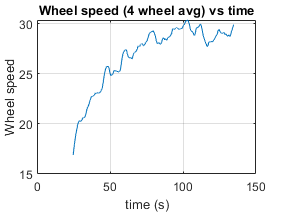

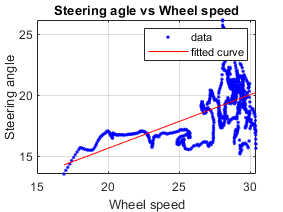


figure(5)
plot(f,wheelspeed_avg,str_a), title('Steering agle vs Wheel speed'),...
    xlabel('Wheel speed'),ylabel('Steering angle'),grid

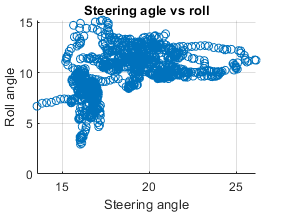

figure(6)
scatter(str_a,roll), title('Steering agle vs roll'),...
    xlabel('Steering angle'),ylabel('Roll angle'),grid